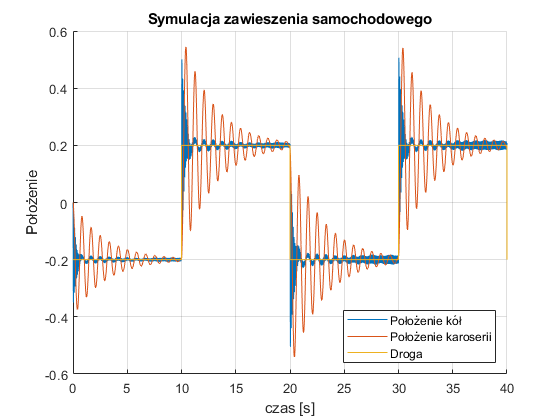

mc = 250;       % kg
mw = 30;        % kg
cc = 15000;     % N/m
cw = 200000;    % N/m
dc = 200;       % Ns/m
dw = 10;        % Ns/m

k    = 100;
beta = 1;
alfa = 1000;

sim('suspension');

t = out.tout;
xw = out.xw.Data;
xc = out.xc.Data;
xg = out.xg.Data;
F = out.F.Data;

figure;
hold on;
grid on;
plot(t,xw);
plot(t,xc);
plot(t,xg);
hold off;
legend("Położenie kół","Położenie karoserii", "Droga","Location","southeast")
xlabel("czas [s]")
ylabel("Położenie")
title("Symulacja zawieszenia samochodowego");

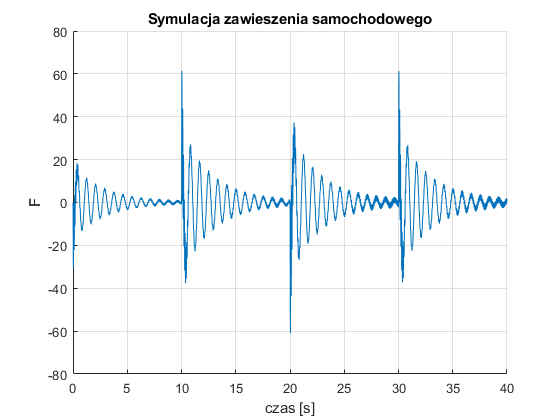

figure;
hold on;
grid on;
plot(t,F);
hold off;
xlabel("czas [s]")
ylabel("F")
title("Symulacja zawieszenia samochodowego");